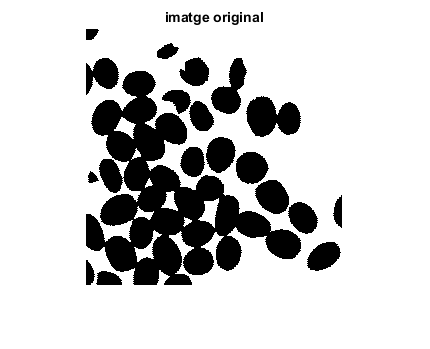

clear
bw = imread('cafe.tif');
bw(bw>0) = 255;
imshow(bw), title('imatge original');

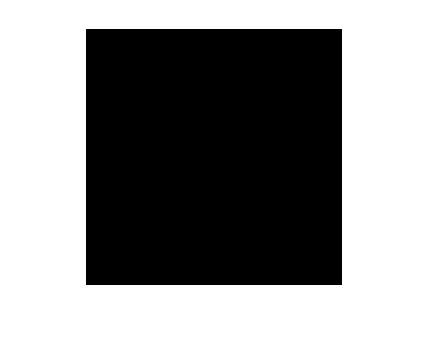

D = -bwdist(bw);
imshow(D)

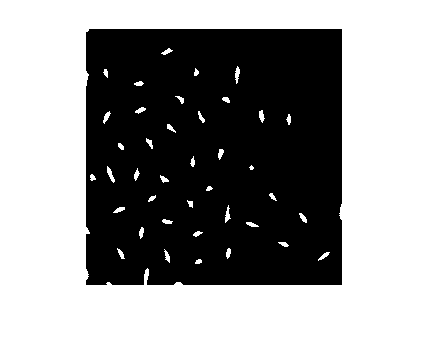

mask = imextendedmin(D,2);
imshow(mask)

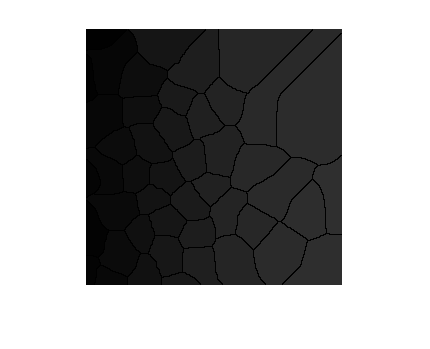

D2 = imimposemin(D,mask);
Ld2 = watershed(D2);
imshow(Ld2)

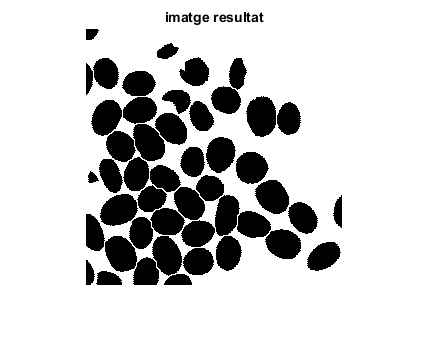

bw(Ld2 == 0) = 255;
imshow(bw), title('imatge resultat');